clc; clear all; close all;
run('variableLoader.m')
%INPUTS
sim('inputs_version.slx');
load('doublet.mat')
input = doublet;
Ts = 0.02;
iodelay = 0;

# SIMO identification - short period mode(5secs)

paramStruct.StopTime = "5";

## elevator input

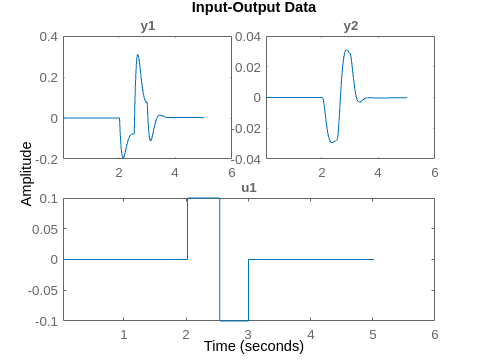

out = sim('elevator_version',paramStruct);
u = out.elevator;
%y1 = squeeze(out.velocity)-25;
%y2 = squeeze(out.gamma);
y3 = squeeze(out.pitch_rate);
y4 = squeeze(out.aoa)-alpha_trim;
%y5 = squeeze(out.height)-50;
%y = [y1 y2 y3 y4 y5];
y = [y3 y4];
% np = [2; 2; 2; 2; 2];
% nz = [1; 1; 2; 1; 1];
np = [2; 2];
nz = [1; 1];
data = iddata(y,u,Ts);
plot(data)

sys_el_1= tfest(data,np,nz,iodelay)

sys_el_1 =
  From input "u1" to output...
         -37.01 s - 127.1
   y1:  -------------------
        s^2 + 14.42 s + 140
 
         -0.03456 s - 37.63
   y2:  ---------------------
        s^2 + 14.44 s + 141.5
 
Continuous-time identified transfer function.

Parameterization:
   Number of poles: [2;2]   Number of zeros: [1;1]
   Number of free coefficients: 8
   Use "tfdata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                          
Estimated using TFEST on time domain data "data".
Fit to estimation data: [96.79;97.8]%            
FPE: 1.274e-14, MSE: 5.892e-06                   
 
Model Properties


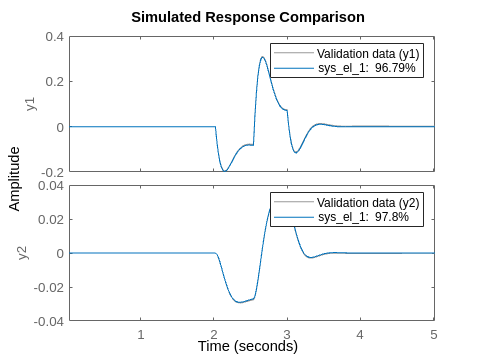

compare(data,sys_el_1)

# SIMO identification - Phugoid mode(20secs)

paramStruct.StopTime = "20";

## elevator input

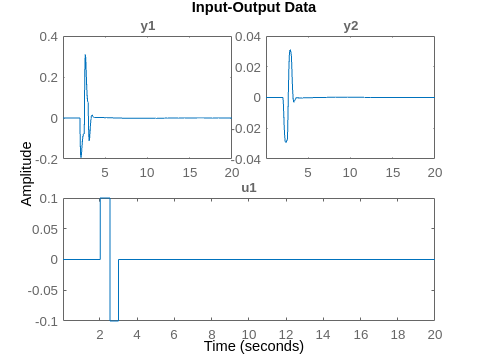

out = sim('elevator_version',paramStruct);
u = out.elevator;
%y1 = squeeze(out.velocity)-25;
%y2 = squeeze(out.gamma);
y3 = squeeze(out.pitch_rate);
y4 = squeeze(out.aoa)-alpha_trim;
%y5 = squeeze(out.height)-50;
%y = [y1 y2 y3 y4 y5];
y = [y3 y4];
% np = [2; 2; 2; 2; 2];
% nz = [1; 1; 2; 1; 1];
np = [2; 2];
nz = [1; 1];
data = iddata(y,u,Ts);
plot(data)

sys_el_2= tfest(data,np,nz,iodelay)

sys_el_2 =
  From input "u1" to output...
         -37.01 s - 127.1
   y1:  -------------------
        s^2 + 14.42 s + 140
 
         -0.03457 s - 37.64
   y2:  ---------------------
        s^2 + 14.44 s + 141.5
 
Continuous-time identified transfer function.

Parameterization:
   Number of poles: [2;2]   Number of zeros: [1;1]
   Number of free coefficients: 8
   Use "tfdata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                          
Estimated using TFEST on time domain data "data".
Fit to estimation data: [96.27;97.42]%           
FPE: 1.067e-15, MSE: 2.005e-06                   
 
Model Properties


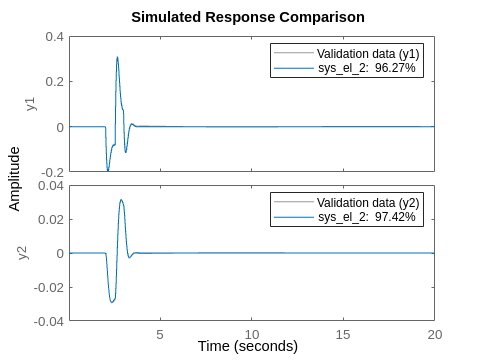

compare(data,sys_el_2)

## throttle input

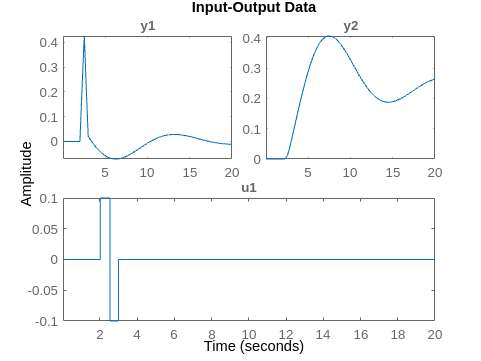

out = sim('throttle_version',paramStruct);
u = out.throttle;
y1 = squeeze(out.velocity)-25;
%y2 = squeeze(out.gamma);
%y3 = squeeze(out.pitch_rate);
%y4 = squeeze(out.aoa)-alpha_trim;
y5 = squeeze(out.height)-50;
%y = [y1 y2 y3 y4 y5];
y = [y1 y5];
% np = [2; 2; 2; 2; 2];
% nz = [1; 1; 2; 1; 1];
np = [2; 3];
nz = [1; 2];
data = iddata(y,u,Ts);
plot(data)

sys_t= tfest(data,np,nz,iodelay)

sys_t =
  From input "u1" to output...
            8.618 s + 1.662
   y1:  -----------------------
        s^2 + 0.2254 s + 0.2156
 
             1.231 s^2 - 0.2573 s + 7.228
   y2:  --------------------------------------
        s^3 + 0.314 s^2 + 0.2008 s + 1.253e-12
 
Continuous-time identified transfer function.

Parameterization:
   Number of poles: [2;3]   Number of zeros: [1;2]
   Number of free coefficients: 10
   Use "tfdata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                          
Estimated using TFEST on time domain data "data".
Fit to estimation data: [95.7;90.79]%            
FPE: 3.698e-10, MSE: 0.0001278                   
 
Model Properties


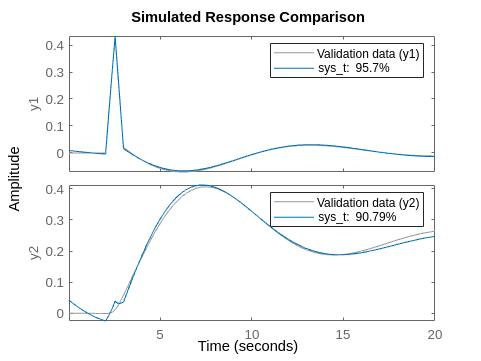

compare(data,sys_t)

# MIMO identification - short period mode(20secs)

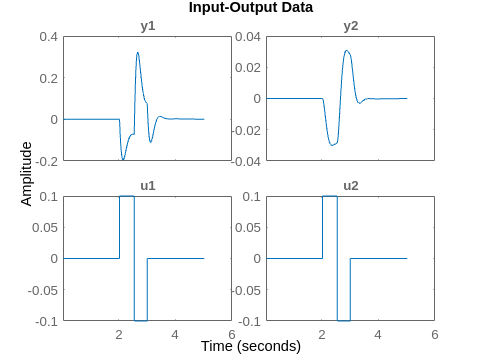

paramStruct.StopTime = "5";
out = sim('fullsys_version',paramStruct);
u1 = out.throttle;
u2 = out.elevator;
u = [u1 u2];
%y1 = squeeze(out.velocity)-25;
%y2 = squeeze(out.gamma);
y3 = squeeze(out.pitch_rate);
y4 = squeeze(out.aoa)-alpha_trim;
%y5 = squeeze(out.height)-50;
%y = [y1 y2 y3 y4 y5];
y = [y3 y4];
% np = [2; 2; 2; 2; 2];
% nz = [1; 1; 2; 1; 1];
np = [2 2; 2 2];
nz = [1 1; 1 1];
data = iddata(y,u,Ts);
plot(data)

sys1= tfest(data,np,nz,iodelay)

sys1 =
  From input "u1" to output...
           2.487 s - 4.061
   y1:  ---------------------
        s^2 + 14.08 s + 403.1
 
           3.605 s - 81.16
   y2:  ---------------------
        s^2 + 19.78 s + 183.7
 
  From input "u2" to output...
          -42.09 s - 124.8
   y1:  ---------------------
        s^2 + 15.93 s + 144.2
 
          -3.744 s + 34.05
   y2:  ---------------------
        s^2 + 23.97 s + 199.1
 
Continuous-time identified transfer function.

Parameterization:
   Number of poles: [2 2;2 2]   Number of zeros: [1 1;1 1]
   Number of free coefficients: 16
   Use "tfdata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                          
Estimated using TFEST on time domain data "data".
Fit to estimation data: [94.85;96.59]%           
FPE: 3.951e-13, MSE: 1.581e-05                   
 


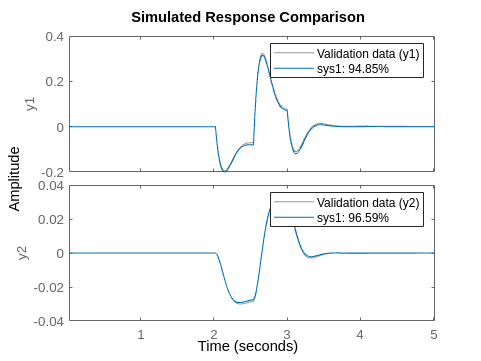

compare(data,sys1)

# MIMO identification - Phugoid mode(20secs)

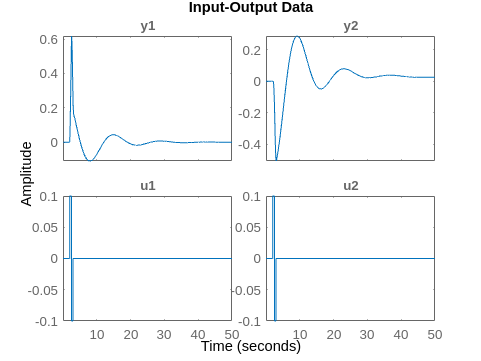

paramStruct.StopTime = "50";
out = sim('fullsys_version',paramStruct);
u1 = out.throttle;
u2 = out.elevator;
u = [u1 u2];
y1 = squeeze(out.velocity)-25;
%y2 = squeeze(out.gamma);
%y3 = squeeze(out.pitch_rate);
%y4 = squeeze(out.aoa)-alpha_trim;
y5 = squeeze(out.height)-50;
%y = [y1 y2 y3 y4 y5];
y = [y1 y5];
% np = [2; 2; 2; 2; 2];
% nz = [1; 1; 2; 1; 1];
np = [2 2; 3 3];
nz = [1 1; 2 2];
data = iddata(y,u,Ts);
plot(data)

sys2= tfest(data,np,nz,iodelay)

sys2 =
  From input "u1" to output...
          -5.951 s - 7.916
   y1:  ---------------------
        s^2 + 11.29 s + 1.561
 
             2.018 s^2 - 39.6 s - 7.285
   y2:  -------------------------------------
        s^3 + 0.3144 s^2 + 0.2574 s + 0.01925
 
  From input "u2" to output...
            12.11 s + 9.095
   y1:  -----------------------
        s^2 + 0.2606 s + 0.2231
 
             0.5482 s^2 + 17.44 s + 6.54
   y2:  --------------------------------------
        s^3 + 0.2584 s^2 + 0.2699 s + 0.008182
 
Continuous-time identified transfer function.

Parameterization:
   Number of poles: [2 2;3 3]   Number of zeros: [1 1;2 2]
   Number of free coefficients: 20
   Use "tfdata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                          
Estimated using TFEST on time domain data "data".
Fit to estimation data: [98.92;97.4]%            
FPE: 5.365e-12, MSE: 1.007e-05                   
 


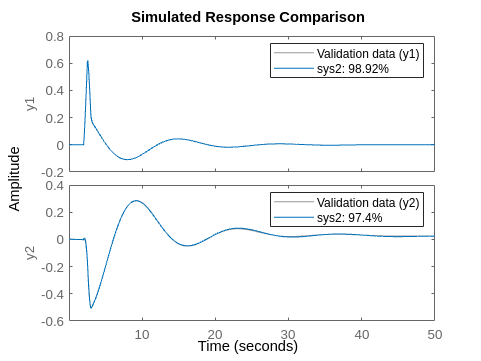

compare(data,sys2)